clear;
a=2

a = 2

sys = @(t,x) [x(1);a-x(2)^2]; 
xmin=-3;xmax=3;sep=1.5;
ymin=-3;ymax=3;
phasefield(sys,xmin:0.25:xmax,ymin:0.25:ymax);
     hold on
     for x0=xmin:sep:xmax
         for y0=ymin:sep:ymax
            [ts,xs] = ode45(sys,[0 6],[x0 y0]);
            plot(xs(:,1),xs(:,2))
         end
     end

     for x0=xmin:sep:xmax
         for y0=ymin:sep:ymax
            [ts,xs] = ode45(sys,[0 -6],[x0 y0]);
            plot(xs(:,1),xs(:,2))
         end
     end

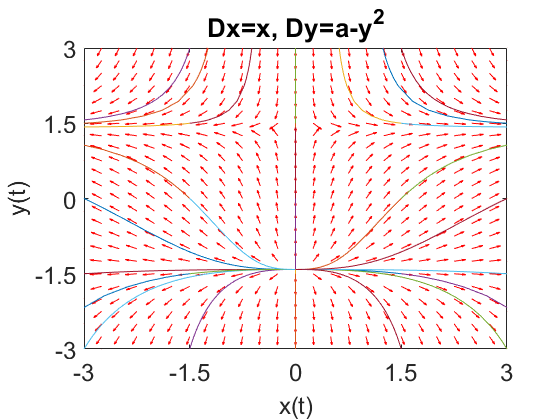

     hold off
axis([xmin xmax ymin ymax])
fsize=18;
title('Dx=x, Dy=a-y^2')
set(gca,'XTick',xmin:sep:xmax,'FontSize',fsize)
set(gca,'YTick',xmin:sep:xmax,'FontSize',fsize)
xlabel('x(t)','FontSize',fsize)
ylabel('y(t)','FontSize',fsize)